# `统计学习方法 第一章 测试`

# **Linear-l**`east-squares Curve Fitting` 

(广东工业大学 自动化学院 控制科学与工程 学一 黄国盛 2112004086  2020.11.28）

% 线性最小二乘法拟合主要是polyfit函数，而polyfit函数的核心是qr函数，即 QR decomposition algorithm ！  
% So, where to find source code of qr() of MATLAB ！！！   [leastsq() of Python ]
% C/C++可见其复杂的实现方式，暂不深究
% 真正体现了矩阵理论中各种分解算法的重要性和实用性！
clear all;
clc ;
close all;

OriginalX = 0:0.001:2*pi;
OriginalY = sin(OriginalX);

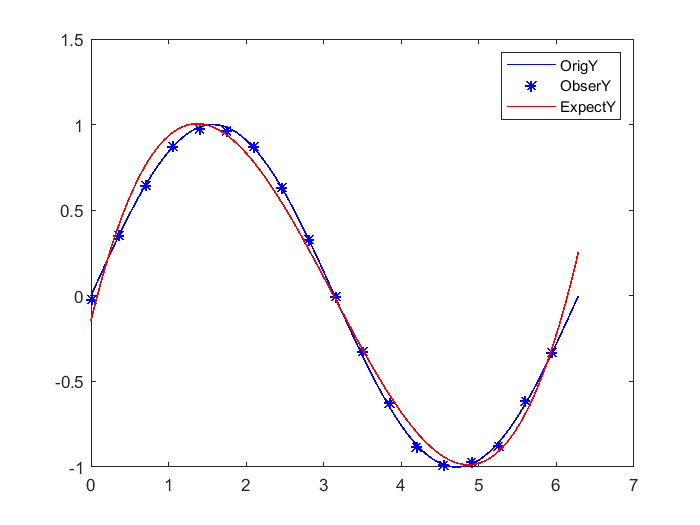

RealX = 0:0.35:2*pi;
RealY = sin(RealX);
ObseNoise_VAR = 0.0001; % 观测噪声的方差 ObserveNoise_VAR   
% 观测噪声: sqrt(ObseNoise_VAR)*randn(1,length(RealX))  工程上采用 高频n次采样均值 降低检测误差
ObserY = RealY + sqrt(ObseNoise_VAR)*randn(1,length(RealX));% + 0.1; % 偏移 用于核对拟合效果

coef = Polyfit_Watson(RealX,ObserY,3);  % 三次基本足够 
ExpectY = polyval(coef,OriginalX); % 在硬件C上最好不要超过四次 并且变量都需强转为single以提高速度并节省内存
    plot(OriginalX,OriginalY,'b',RealX,ObserY,'b*',OriginalX,ExpectY,'r','LineWidth',1)
    legend('OrigY', 'ObserY', 'ExpectY');